clear all; close all; clc;


# dati problema

%%DATI

% x1 = angle of attack
% x2 = pitch angle
% x3 = pitch rate
% x4 = altitude
% y1 = pitch angle
% y2 = altitude
% y3 = velocità * angolo di v rispetto all'orizzonte

% matrici del sistema
A = [-1.2822  0      0.98     0
     0        0      1        0
     -5.4293  0      -1.8366  0
     -128.2   128.2  0        0];

B = [-0.3
      0
      -17
      0   ];

C = [0       1      0  0
     0       0      0  1
     -128.2  128.2  0  0];

D = [0
     0
     0];
% stati iniziali
x0 = [deg2rad(0) deg2rad(15) 0 -300];

% riferimento
x_ref = [0 0 0 0]; % si considera come eq = 0 questio stati [0 0 128.2 5000]

% vincoli su ingresso
u_max = deg2rad(15);
u_min = deg2rad(-15);
% Vincoli slew rate ingresso 
slewrateMax = deg2rad(30);
slewrateMin = deg2rad(-30);

%vincoli su stato 2
x2_min = deg2rad(-20);
x2_max = deg2rad(20);

%vincoli su stato 4
over_shot_constraint = -0.01 * x0(4);

C_states = eye(length(A));
D_states = zeros(length(B), 1);


# dati simulink

T_sim=10; %tempo simulazione

%vincolo in ingresso
sat_min=u_min;
sat_max=u_max;
slewrateMax; slewrateMin; 

%vincolo stato 2
x2_min; x2_max;

%vincolo stato 4
over_shot_constraint;

# lqr continuo


sys = ss(A, B, C, D);
s = tf('s');

C_states = eye(length(A));
D_states = zeros(length(B), 1);

Q1 = 1*eye(length(A));
R1 = 1;
[k_LQ1, P, cl_poles] = lqr(A, B, Q1, R1); 

Q2 = 1000*eye(length(A));
R2 = 1;
[k_LQ2, P, cl_poles] = lqr(A, B, Q2, R2); 

Q3 = 1*eye(length(A));
R3 = 100;
[k_LQ3, P, cl_poles] = lqr(A, B, Q3, R3); 

Q4 = 1*eye(length(A));
R4 = 10000;
[k_LQ4, P, cl_poles] = lqr(A, B, Q4, R4); 


#  sampling time to discretize

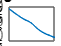

%% 2) 
sigma(sys)

[sv,w_out] = sigma(sys);

for i = 1:length(w_out)
    if sv(i) <= 1
        tep = i;
        break
    end
end

omega_taglio = w_out(i)

omega_taglio = 46.3249

gain_taglio = sv(i);  % non proprio 1 ma vabbe
omega_sampling = 2 * omega_taglio;
T_sampling = 2*pi/omega_sampling;

# disctretize system

sysd = c2d(sys,T_sampling);

Q_d = Q4; 
R_d = R4;

[Klqr_d, P_d, CLP_d] = dlqr(sysd.A,sysd.B,Q_d,R_d);
% open('LQR_discrete') % --------------------------------------------------
% sim('LQR_discrete') % ---------------------------------------------------
% keyboard % --------------------------------------------------------------

# ES.3 MPC 

P_MPC = P_d;  % S from the theory: the bound of mpc;  to achive stationary solution for every N we set S = P stationary solution of the riccati eq.

NOTA uso:

 MPC si definisce qui, poi volta per volta si usa il  simulik giusto  aggiungendo un vnicolo. i vincoli sono definiti nella funzione mpc da usare che simulink prende autonomente. QUESTO è IL PROGRAMMA CHE GIRA, BISOGNA FARE TUTTE LE OSS DEL CASO. MANCA QUELLO CON OBSERVER

Ts=T_sampling; %to avoid undefined error
Q_MPC = Q_d; R_MPC = R_d; P_MPC = P_d;

SetN = [20 30 90];

% open('MPC_noConstraints') % ---------------------------------------------
% sim('MPC_noConstraints') % ----------------------------------------------
% keyboard % --------------------------------------------------------------

N = 1; %to verify convergence
%N = SetN(3); %normal finete horizon of work

# MPC KALMAN FILTER

using kalman filter with lqr, than pass A,B ecc at mpc